# **변경사항**

**2023.01.26**

- 3d plot 시점 정해서 svg로 추출

- 한 개의 channel로만 구성된 community의 색깔 통일

- parameter 이름 변경 및 설명 보강

- node에 커서 올리면 community와 degree 정보 출력

- 좌표축 표시/숨기기 옵션

### 2023.01.10

- macOS 설정 방법 설명 추가

- node 삭제 기능 추가

- edge color 설정 방법 변경

- edge가 검은색으로 나오는 오류 해결

- svg export 추가

- 2d network 예시 추가

### 2022.08.25

- spike 개수가 2 이상인 경우에만 sync score 계산하도록 수정

- network plot에서 node 크기를 키우고 채널 번호가 보이도록 수정

# 코드 실행 전 필수 수행 절차

## (1) matlab add-on 설치

다음 add-on을 설치합니다.

- signal processing toolbox

- statistics and machine learning toolbox

## **(2) Python 설치 및 설정**

### **(2.1) MacOS on Apple Silicon (e.g., M1, M2)의 경우**

- [https://www.anaconda.com/products/distribution#macos](https://www.anaconda.com/products/distribution#macos) 에서 Anaconda Distribution 다운로드하여 설

- terminal 실행

- 아래 명령어 입력하여 가상환경 생성

- `matlab_python`은 가상환경 이름이며 다른 이름으로 바꾸어도 됨

- `python==3.9.2` 는` 3.9.2 `버전의 파이썬을 설치한다는 뜻이며 다른 버전으로 바꾸어도 됨

`     4. 아래 명령어 입력하여 가상환경 활성화. (matlab_python)이라는 문구가 뜬다면 성공`

`     5. 가상환경이 활성화 된 상태에서 아래 명령어를 한 줄씩 입력하여 필요한 패키지 설치 (kaleido는 오류가 많습니다. svg파일을 추출할 필요가 없을 경우 설치하지 않아도 됩니다)`

`     6. python 설치 경로 찾기`

                [1] 가상환경이 활성화 된 상태에서 terminal에 아래 명령어를 입력하여 python을 실행  

               [2]  python이 실행된 상태에서 terminal에 아래 명령어를 입력하여 설치된 파이썬의 경로를 출력

아래와 같이 경로가 하나 출력됩니다.

    

이 내용을 복사합니다.

### **(2.2) Windows 10**

- https://repo.anaconda.com/miniconda/Miniconda3-py38_23.5.0-3-Windows-x86_64.exe 를 다운받아 설치합니다. 

- Advanced installation option 단계에서 모든 항목에 다 체크합니다 (create start menu shortcut, add miniconda 3 to my Path environment variable...)

- https://developer.microsoft.com/ko-kr/windows/downloads/windows-sdk/ 에서 windows 10 sdk를 설치합니다.

- https://aka.ms/vs/17/release/vs_buildtools.exe 를 다운로드하고 실행합니다. 항목 선택 매뉴에서 c++... 을 체크하고 설치합니다.

- 명령 프롬프트를 실행합니다.

- 명령 프롬프트  창에 바로 아래 내용을 한 줄씩 입력하고 엔터를 칩니다.  각 명령어는 패키지 하나를 설치하는 명령어입니다.  ` (kaleido는 오류가 많습니다. svg파일을 추출할 필요가 없을 경우 설치하지 않아도 됩니다)`

       7. 입력창에 python을 입력하여 python을 실행합니다. python 버전이 3.8x인지   확인합니다.

          8.. 아래 내용을 한 줄씩 입력하고 엔터를 칩니다. 출력되는 내용이 설치된 파이썬의 경로입니다. 이 내용을 복사합니다(저는 macos에서 진행했기 때문에 윈도우와 파이썬 경로가 다릅니다).

# **1. 2d network 그리기**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

- **network plot 그리기(3d)**

## **1.1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/jmmoon/Documents/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 소요시간 측정

Elapsed time is 40.487141 seconds.


## **1.2. networkAnalyzer 인스턴스 생성**

**(class) networkAnalyzer**

- 데이터를 저장하고, 그 데이터를 가지고 계산을 수행하고 그래프를 그리는 작업을 수행하는 객체입니다.

- 아래 예제에서는 na라는 이름을 가진 객체를 생성했습니다. na에게 데이터 A를 할당해 주면 앞으로 그 데이터에 대한 작업은 모두 na가 수행합니다. A에 대한 정보를 얻고 싶을 때도 항상 na를 통해서 얻습니다.

- 새로운 데이터 B를 분석할 때는 na가 아닌 다른 이름의 객체를 새로 생성한 다음 na에서 했던 것과 같은 코드를 실행하면 됩니다.

**    paramter 3개**

- `filepath`: 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- `pythonpath`: 코드 수행 전 필수 절차의 2번 항목에서 얻은 python 설치 경로

- `savepath`: csv 파일과 그래프 파일을 저장하는 경로

tic
%  networkAnalyzer 클래스 인스턴스 생성
na2d = networkAnalyzer( ...
    "/Users/jmmoon/Documents/GitHub/neurosignal-matlab", ... %filepath
    "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python", ... %pythonpath
    "/Users/jmmoon/Documents/GitHub/neurosignal-matlab/network_save" ... %savepath
    ); 

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python"
          Library: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/lib/libpython3.9.dylib"
             Home: "/Users/jmmoon/opt/anaconda3/envs/matlab_python"
           Status: Terminated
    ExecutionMode: OutOfProcess


toc

Elapsed time is 7.405264 seconds.


## **1.3. 데이터 파일을 networkAnalyzer에 전달 **

na2d.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

Deleted previous data
Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
num

## **1.4. 사용하지 않는 채널 제거**

normalizing을 하게 되면서 계산 횟수가 1000배 이상 증가하였기 때문에 계산 속도가 매우 느려졌습니다. 따라서 빠르게 결과를 확인하기 위해 채널을 10개만 남겨놓겠습니다. 즉 11번-64번 채널을 모두 제거하겠습니다.

`(method) deleteChannel`

- 제거할 채널의 목록을 array로 정해주면 해당 채널을 제거합니다.

- matlab에서 array를 만드는 다양한 방법을 이용해 제거할 채널의 목록을 만들면 됩니다.

-     연속되는 숫자는 :를 사용합니다.

-     여러 array를 연결할 때는 [] 안에서 ,로 연결합니다 (아래 예시 참고)

**    paremeter 1개**

- `delete_channel_list`

delete_channel_list = [11:40, 41:64];
na2d.deleteChannel(delete_channel_list);

Deleted channal 11
63 channels left
Deleted channal 12
62 channels left
Deleted channal 13
61 channels left
Deleted channal 14
60 channels left
Deleted channal 15
59 channels left
Deleted channal 16
58 channels left
Deleted channal 17
57 channels left
Deleted channal 18
56 channels left
Deleted channal 19
55 channels left
Deleted channal 20
54 channels left
Deleted channal 21
53 channels left
Deleted channal 22
52 channels left
Deleted channal 23
51 channels left
Deleted channal 24
50 channels left
Deleted channal 25
49 channels left
Deleted channal 26
48 channels left
Deleted channal 27
47 channels left
Deleted channal 28
46 channels left
Deleted channal 29
45 channels left
Deleted channal 30
44 channels left
Deleted channal 31
43 channels left
Deleted channal 32
42 channels left
Deleted channal 33
41 channels left
Deleted channal 34
40 channels left
Deleted channal 35
39 channels left
Deleted channal 36
38 channels left
Deleted channal 37
37 channels left
Deleted channal 38
36 channe

## **1.5. 노드 좌표 설정**

### **1.5.1. 방법 1 : 채널 각각의 위치를 따로 설정**

method `setChannelPosition3d`

input argument:

- channel number

- 해당 channel의 x좌표

- 해당 channel의 y좌표

- 해당 channel의 z좌표

x, y 좌표는 좌표평면의 1사분면을 생각하면 됩니다. (0,0)의 한 칸 위가 (0,1)이고 한 칸 오른쪽이 (1,0)입니다. 아래 코드로 설정한 위치를 그림으로 그리면 아래 그림처럼 됩니다.

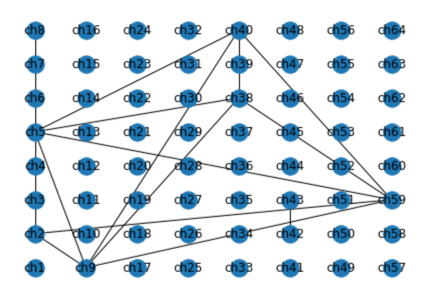

2d network이므로 높이를 모두 0으로 설정합니다.

%                 channlNum x  y  z
na2d.setChannelPosition3d(1 , 0, 0, 0)

set channel 1's position as (0.000000, 0.000000, 0.000000)


na2d.setChannelPosition3d(2 , 0, 1, 0)

set channel 2's position as (0.000000, 1.000000, 0.000000)


na2d.setChannelPosition3d(3 , 0, 2, 0)

set channel 3's position as (0.000000, 2.000000, 0.000000)


na2d.setChannelPosition3d(4 , 1, 0, 0)

set channel 4's position as (1.000000, 0.000000, 0.000000)


na2d.setChannelPosition3d(5 , 1, 1, 0)

set channel 5's position as (1.000000, 1.000000, 0.000000)


na2d.setChannelPosition3d(5 , 1, 2, 0)

set channel 5's position as (1.000000, 2.000000, 0.000000)


na2d.setChannelPosition3d(6 , 2, 0, 0)

set channel 6's position as (2.000000, 0.000000, 0.000000)


na2d.setChannelPosition3d(7 , 2, 1, 0)

set channel 7's position as (2.000000, 1.000000, 0.000000)


na2d.setChannelPosition3d(8 , 2, 2, 0)

set channel 8's position as (2.000000, 2.000000, 0.000000)


na2d.setChannelPosition3d(9 , 3, 0, 0)

set channel 9's position as (3.000000, 0.000000, 0.000000)


na2d.setChannelPosition3d(10 , 3, 1, 0)

set channel 10's position as (3.000000, 1.000000, 0.000000)


### **1.5.2. 방법 2 : 모든 채널의 위치를 한꺼번에 설정**

채널 개수 x 3 크기의 array에 위치를 한꺼번에 입력합니다. 채널 번호가 빠른 채널의 위치부터 입력합니다. 예를 들어 채널 번호가 [1,3,4,5,10]이라면, 이 순서로 빈칸 없이 입력합니다 (예를 들어, 2번 채널의 위치는 입력하지 않습니다)

positions_input_array = [
    0,0,0; 
    0,1,0;
    0,2,0;
    1,0,0;
    1,1,0;
    1,2,0;
    2,0,0;
    2,1,0;
    2,2,0;
    3,0,0;    
    ];
na2d.setChannelPosition3dArray(positions_input_array)

set channel 1's position as (0.000000, 0.000000, 0.000000)
set channel 2's position as (0.000000, 1.000000, 0.000000)
set channel 3's position as (0.000000, 2.000000, 0.000000)
set channel 4's position as (1.000000, 0.000000, 0.000000)
set channel 5's position as (1.000000, 1.000000, 0.000000)
set channel 6's position as (1.000000, 2.000000, 0.000000)
set channel 7's position as (2.000000, 0.000000, 0.000000)
set channel 8's position as (2.000000, 1.000000, 0.000000)
set channel 9's position as (2.000000, 2.000000, 0.000000)
set channel 10's position as (3.000000, 0.000000, 0.000000)


## **1.6. spike detection**

필터링 후 spike detection을 수행합니다. 방법은 summary_examples_multichannel.mlx 파일에서와 동일합니다.

tic %실행시간 측정 시작
na2d.bandPass([300,3000])
na2d.detectSpikes(4,2,2)

channel 1 number of spikes found : 61
channel 2 number of spikes found : 131
channel 3 number of spikes found : 140
channel 4 number of spikes found : 313
channel 5 number of spikes found : 351
channel 6 number of spikes found : 86
channel 7 number of spikes found : 82
channel 8 number of spikes found : 175
channel 9 number of spikes found : 147
channel 10 number of spikes found : 108


ans = 10×1 table
              n_spike
              _______

    node1        61  
    node2       131  
    node3       140  
    node4       313  
    node5       351  
    node6        86  
    node7        82  
    node8       175  
    node9       147  
    node10      108  


toc %실행시간 측정 끝

Elapsed time is 5.310557 seconds.


### **1.6.1 channel별 spike 평균 amplitude**

(2023년 7월 18일 추가)

`(method) getMeanSpikeAmplitude`

- 제거할 채널의 목록을 array로 정해주면 해당 채널을 제거합니다.

- matlab에서 array를 만드는 다양한 방법을 이용해 제거할 채널의 목록을 만들면 됩니다.

-     연속되는 숫자는 :를 사용합니다.

-     여러 array를 연결할 때는 [] 안에서 ,로 연결합니다 (아래 예시 참고)

- 오류가 나면, 입력한 범위 안에 spike가 없어서 생긴 오류일 가능성이 높습니다. 여러 범위 값을 시도해 보세요.

**    paremeter 3개**

- `range_start: `계산에 포함할 spike 시간 범위의 시작점 (초 단위)

- `range_end: `계산에 포함할 spike 시간 범위의 끝점 (초 단위)

- `isRaw``: true`이면 raw signal에서의 amplitude로 계산합니다. `false`이면 filtered signal에서의 amplitude로 계산합니다.

na2d.getMeanSpikeAmplitude(5,10, true)

ans = 10×1 table
              average_amp
              ___________

    node1     0.00031438 
    node2     0.00011738 
    node3     0.00014856 
    node4     0.00013248 
    node5     1.5719e-05 
    node6     5.3633e-06 
    node7     1.7303e-05 
    node8      0.0001497 
    node9     0.00012938 
    node10    0.00010101 


### **1.6.2. 통합 raster plot **

`(class) drawer_raster_instance`

- raster plot을 만드는 작업을 하는 객체를 생성하는 class입니다. 향후 summary_examples_multichannel, summary_examples_�firing_rate 등 여러 파일에 서로 다르게 작성되어 있는 raster plot 그리는 코드를 이 class를 이용해 통합하고자 합니다.

`(method) drawRaster`

- 채널 하나의 raster plot을 그립니다. 

**    paremeter 1개**

- `channel: `raster plot을 그릴 `channel` object. spike detection을 이미 한 상태여야 함

- `color: `계산에 포함할 spike 시간 범위의 시작점 (초 단위)

`(method) drawRasterAll`

- 채널 여러 개의 raster plot을 한번에 그립니다. networkAnalyzer 

**    paremeter 2개**

- `multichannal_instance: `raster plot을 그릴 `channel` object들을 보유하고 있는 object. 우선 networkAnalyzer를 지원하도록 코드를 작성하였습니다. 향후 summary_examples_multichannel나 summary_examples_�firing_rate에 있는 obejct들도 지원하게 수정하겠습니다.

- `color: `계산에 포함할 spike 시간 범위의 시작점 (초 단위)

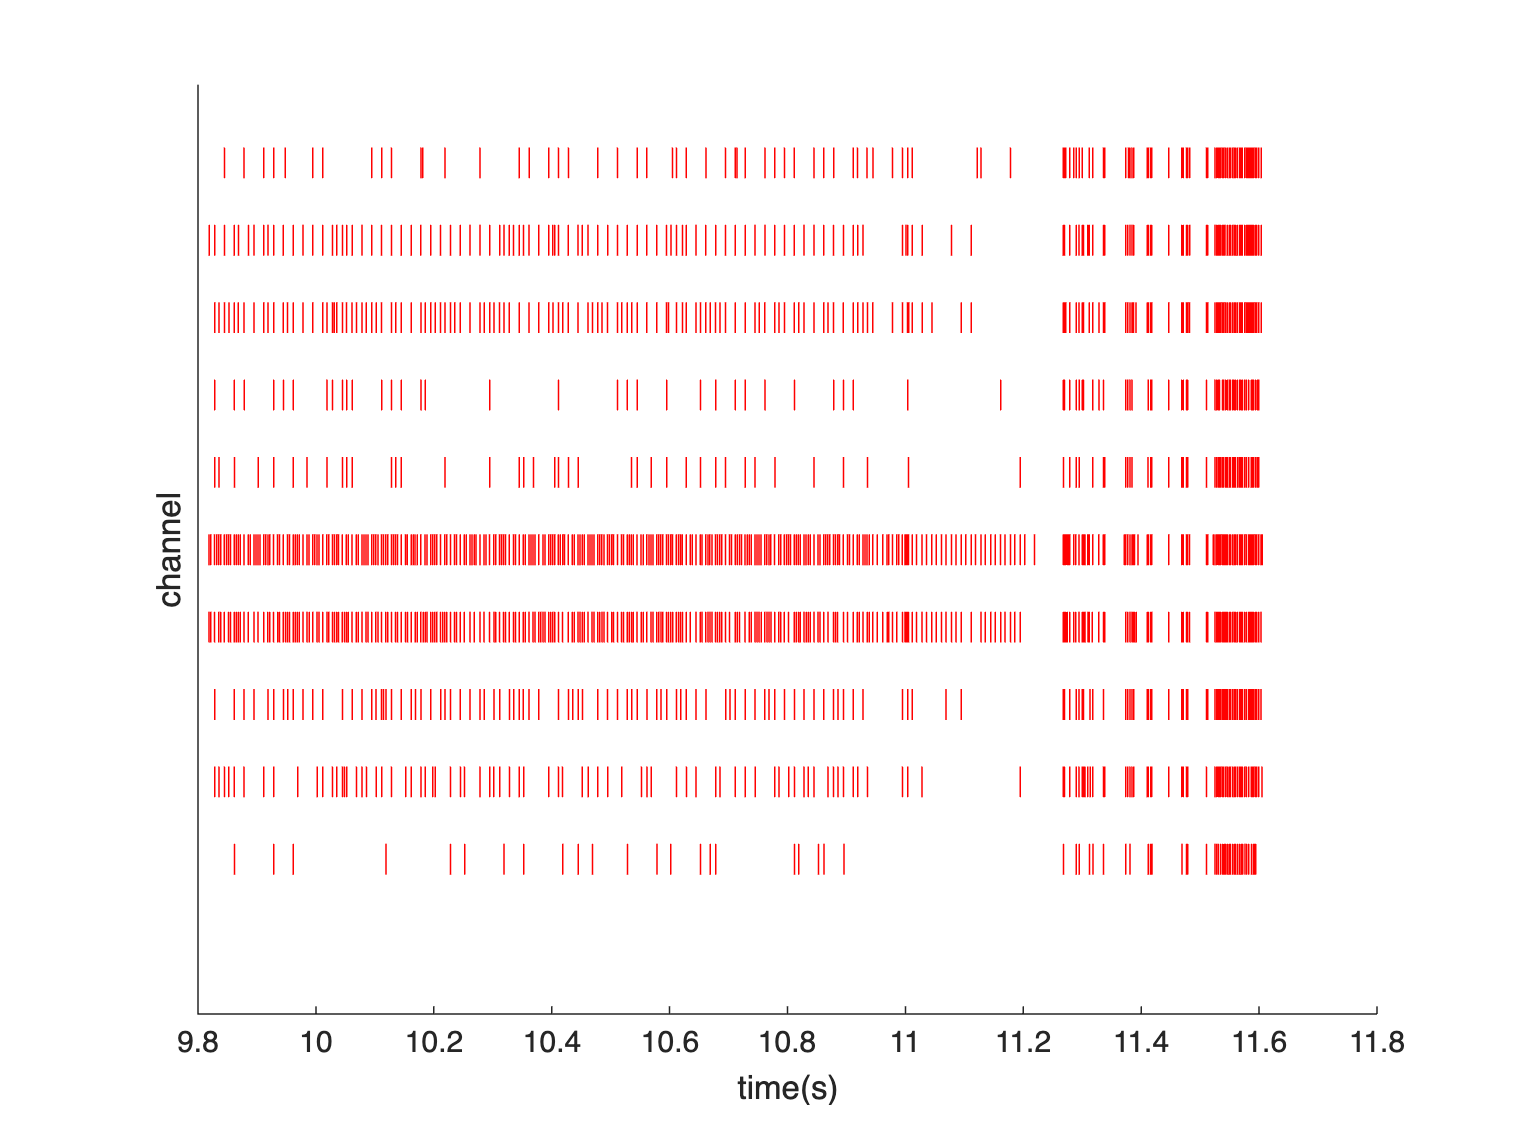

ans =     10
     9
     8
     7
     6
     5
     4
     3
     2
     1


drawer_raster_instance = drawer_raster();
%multiple raster plot
figure
drawer_raster_instance.drawRasterAll(na2d, 'red')

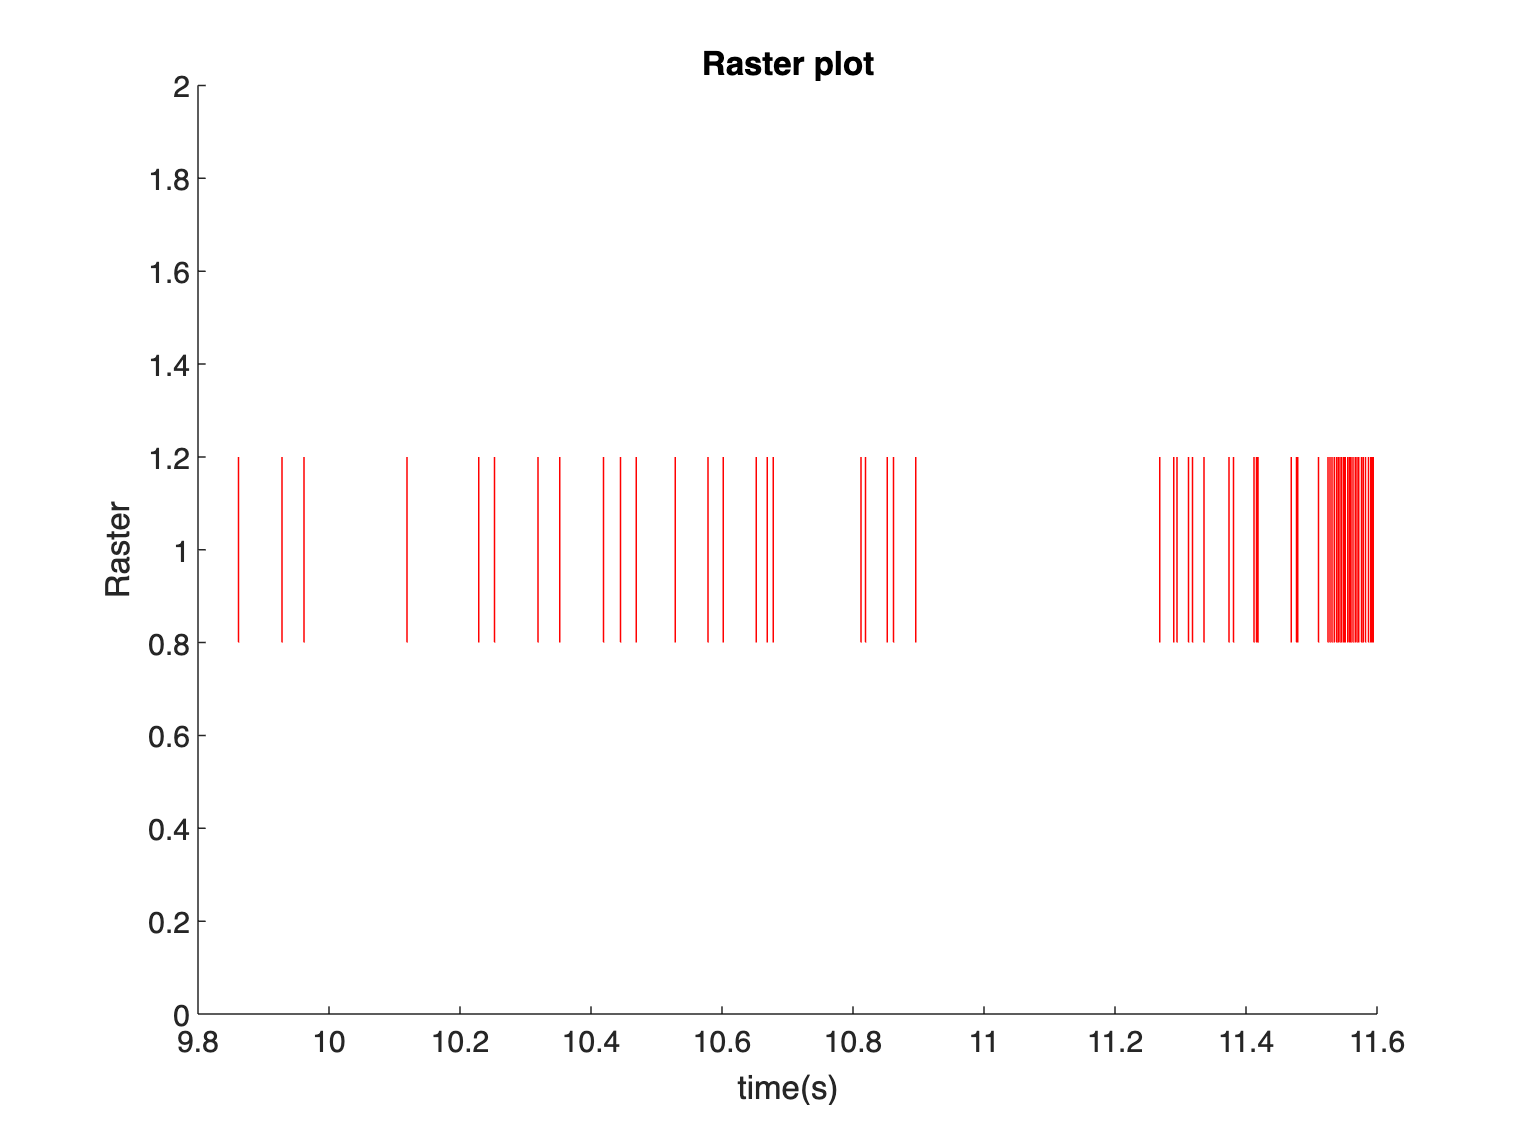


figure
% signle raster plot
                                        % channel 번호
drawer_raster_instance.drawRaster(na2d.channels(1), 'red')

## **1.7. sync score 계산 및 확인**

**(method) spikeDist**

- pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도 (= 1 - 거리)를 측정합니다.

- spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 sync score 계산값이 NaN이 됩니다.

- NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

**    paramter 3개**

- `thres`: thres 값을 0.5로 설정하면, sync score 0.5 이상일 경우에만 두 채널이 연결된 것으로 간주합니다. 이 값은 네트워크를 생성할 때 사용되는 값으로, `thres`에 의해 걸러진 연결은 edge로 만들어지지 않습니다. 네트워크를 그릴 때 사용하는 범위 값 (`edge_lim`)은 이미 만들어진 네트워크를 그릴 때 보여 줄 edge를 거르는 범위입니다.

- `is_normalize`: true로 하면 random spike trains 두 개를 생성해 그 사이의 sync score를 계산하는 작업을 n_simul번 반복하고 그 결과 얻은 n_simul개 sync score의 평균값을 원래 sync score에서 뺍니다 (0보다 작은 값이 나올 경우 0으로 만듭니다). **계산 횟수가 n_simul배 늘어나므로 계산에 시간이 매우 많이 걸립니다 (채널 10개로 약 20분이 걸립니다).** false로 하면 위 작업을 수행하지 않고 원래 sync score 값을 사용합니다.

- `n_simul`: random spike trains 생성 갯수. Reference 논문에서는 1000회입니다.

calculating sync score between 1th and other channels...
calculating sync score between 2th and other channels...
calculating sync score between 3th and other channels...
calculating sync score between 4th and other channels...
calculating sync score between 5th and other channels...
calculating sync score between 6th and other channels...
calculating sync score between 7th and other channels...
calculating sync score between 8th and other channels...
calculating sync score between 9th and other channels...
calculating sync score between 10th and other channels...


filepath_score_matrix = "/Users/jmmoon/Documents/GitHub/neurosignal-matlab/pkls/score_matrix.npy"

filepath_positions = "/Users/jmmoon/Documents/GitHub/neurosignal-matlab/pkls/positions.pkl"

tic %실행시간 측정 시작
thres = 0.1; %sync score 0.3 이상일 경우에만 연결된 것으로 간주 (network를 그릴 때에만 적용됨)
           % thres  is_normalize, n_simul
na2d.spikeDist(thres, false, 1000);

%na.spikeDist(thres, true, 1000);
toc %실행시간 측정 끝

Elapsed time is 1.417968 seconds.


아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na2d.syncScores

ans = 10×10 table
               node1      node2      node3      node4      node5      node6      node7      node8      node9     node10 
              _______    _______    _______    _______    _______    _______    _______    _______    _______    _______

    node1           0    0.52083    0.52736    0.32086    0.29126    0.65306    0.65734    0.47458    0.51923    0.56805
    node2     0.52083          0    0.70849    0.58559    0.53527    0.64516    0.67606    0.75163    0.74101    0.68619
    node3     0.52736    0.70849          0    0.60927    0.56619    0.67257    0.65766        0.8    0.85


max(na2d.syncScores{:,:}) %각 channel별 sync score 최댓값

ans =     0.6573    0.7516    0.8502    0.9247    0.9247    0.7738    0.7738    0.8447    0.8502    0.7608



max(max(na2d.syncScores{:,:})) %전체 sync score 중 최댓값

ans = 0.9247

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na2d.nConnects

ans = 10×1 table
              number of connected
              ___________________

    node1              9         
    node2              9         
    node3              9         
    node4              9         
    node5              9         
    node6              9         
    node7              9         
    node8              9         
    node9              9         
    node10             9         


max(na2d.nConnects{:,:}) %각 channel별 degree 최댓값

ans = 9


max(max(na2d.nConnects{:,:})) %전체 degree 중 최댓값

ans = 9

## **1.8. network 그룹 개수 파악하기**

network plot을 그리기 전에 각 그룹에 서로 다른 색깔을 할당하기 위해 그룹 개수를 먼저 파악합니다. 실행에 10초 정도 소요됩니다.

tic % 실행시간 측정 시작
n_group = na2d.get_group_info();

ans = 0

number of groups: 2
number of channels per group:
   group / number of channels

ans = 2×2 int64 matrix
   2   8
   1   2


toc % 실행시간 측정 끝

Elapsed time is 12.862392 seconds.


random_node_color = rgb2hex(rand([n_group 3]));

## **1**.9. network plot 그리기(2d)

figure 3 a, b, c, d, e의 (ii)

`(method) louvain`

- 네트워크 모양을 plot으로 그릴 때 필요한 python의 matplotlib 라이브러리가 matlab 상에서 py.xxx 명령어로 실행되지 않아서, pyrun("xxx")를 이용해 네트워크를 만들고 그림을 그리는 코드가 들어 있는 `drawnx.py `파일을 통째로 실행합니다.

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

**    paremeter 15개**

- `node_size_basic`

- `node_size_multiplier`

- `startcolor_edge`

- `endcolor_edge`

- `color_list_node`

- `degree_lim`

- `edge_lim`

- `edge_colorbar_lim`

- `display_community_color`

- `display_degree`

- `display_sync_score`

- `display_axes`

- `camera_up`

- `camera_center`

- `camera_eye`

#### [1-2] Node size parameters

노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. 

node size = node_size_basic + node_size_multiplier * relative_degree

따라서 degree가 가장 작은 노드의 크기는 node_size_basic, degree가 가장 큰 노드의 크기는 node_size_basic+node_size_multiplier가 됩니다.

- `node_size_basic`: degree가 가장 작은 node의 크기

- `node_size_multiplier`: degree가 1씩 커질 때마다 node size가 얼마나 커질지를 결정합니다. degree는 max degree = 1, min degree = 0으로 normalize한 값을 사용합니다.

%1
node_size_basic = 10;

%2
node_size_multiplier = 20;

#### [3-5] Color paramters

edge와 node의 색깔을 결정합니다. Edge의 값은 연속형이기 때문에 color scale로 색깔을 표시하는 반면, node의 group 번호는 이산형이기 때문에 color list로 색깔을 표시합니다. Edge 색깔을 위한 color scale은 시작 색깔 (`startcolor_edge`)과 종료 색깔 (`endcolor_edge`)을 정하여 생성합니다. Node 색깔을 위한  color list는 직접 입력하거나, 1.8에서 생성된 `random_node_color`를 사용할 수 있습니다. 색깔은 모두 hex 코드로 입력하며, hex 코드는 https://www.color-hex.com/ 에서 검색해서 찾으시면 됩니다.

- `startcolor_edge`: edge 색깔을 위한 color scale의 시작 색깔 hex code

- `endcolor_edge`: edge 색깔을 위한 color scale의 종료 색깔 hex code

- `color_list_node`: node 그룹 개수에 맞게 색깔 hex 코드의 array를 만들어 입력합니다. 이 예제에서는 그룹이 2개이므로 원소가 2개인 array를 만듭니다. 

%3
startcolor_edge = '#9fcbee'; % #9fcbee indicates skyblue

%4
endcolor_edge =  '#01016f'; % #01016f indicates indico

%5
% color_list_node = ['#802000', '#ecdec2']; % 직접 지정할 때
% #802000 indicates brown, #ecdec2 indicates yellow

color_list_node = random_node_color;

#### [6-7] Display range paramters

네트워크를 그림으로 그릴 때 특정 범위 밖의 node나 edge를 숨기는 기능입니다. 앞에서 `spikeDist를` 실행할 때 사용한 `thres`와는 달리, 계산과정에는 영향을 미치지 않습니다. 계산과정에서 edge의 유무에 따라 group 형성 결과가 달라지기 때문에, `thres` 값 조절과 여기의 파라미터 값 조절은 서로 다른 역할을 합니다.

- `degree_lim`: Degree가 이 범위 내에 있는 node만 plot에 표시됩니다. 앞에서 channel을 지우는 것과 달리, 계산과정 자체에는 포함됩니다. na.nConnects로 degree 범위를 확인한 다음 적절한 값을 설정하세요.

- `edge_lim`: % Sync score가 이 범위 내에 있는 edge만 plot에 표시됩니다. na.syncScores로 sync score 범위를 확인한 다음 적절한 값을 설정하세요.

%6
degree_lim = [0, 100]; 

%7
edge_lim = [thres, 1]; 

#### [8] Colarbar range paramter

여러 plot의 sync score colorbar 범위를 통일시키기 위한 기능입니다.각 plot마다 edge value 값의 범위가 다 다르기 때문에, 여러 plot의 edge들에서 같은 edge 값이면 같은 색으로 칠해지도록 하기 위함입니다.

- `edge_colorbar_lim`: colorbar의 범위를 정합니다. 이 값은 edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.

%8
edge_colorbar_lim = [thres, 1]; 

#### [9-12] Display on/off options

그림에서 특정 요소를 표시할지 여부를 결정합니다. true로 지정하면 해당 요소를 표시합니다.

- `display_community_color`: true이면 각 node를 소속 group의 색으로 칠합니다.

- `display_degree`: true이면 degree에 따라 node 크기를 다르게 그립니다.

- `display_sync_score`: true이면 sync score에 따라 edge 색깔을 다르게 합니다.

- `display_axes`: true이면 좌표축을 표시합니다.

%9
display_community_color= true;

%10
display_degree = true;

%11
display_sync_score = true;

%12
display_axes = false;

#### [13-15] Camera options

[https://wearablelab-camera-5ti4.onrender.com](https://wearablelab-camera-5ti4.onrender.com) 에서 적절한 각도를 설정한 뒤 (접속에 1분 정도 걸립니다), plot 위에 나타나는 좌표값에서 (scene.camera... 부분)

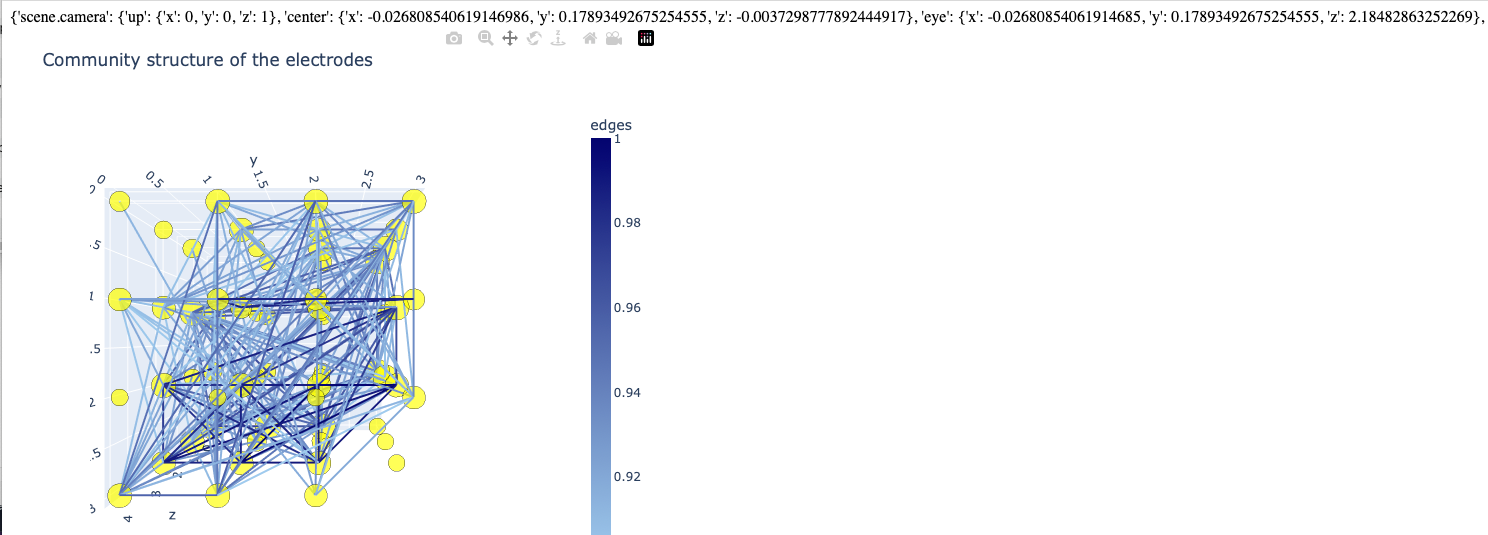

up, center, eye의  x,y,z좌표를 가져와 아래에 순서대로 입력합니다. 또는 [https://plotly.com/python/3d-camera-controls/](https://plotly.com/python/3d-camera-controls/) 의 설명을 참고하여 값을 정합니다.

- `up`: orbital rotation 기능을 사용하면 바뀌는 값입니다. 2d network에서는 사용할 일이 없습니다.

            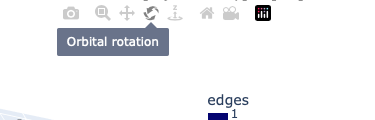

- `center`: pan 기능을 사용해 plot 자체를 상하좌우로 움직이면 바뀌는 값입니다. Colorbar와 plot이 겹치지 않도록 할 때 사용합니다.

                        

- `eye`: turntable rotation 기능을 사용해 plot을 돌리면 바뀌는 값입니다. html 파일을 열면 기본적으로 이 기능이 켜져 있습니다. 

                

%13
camera_up = [0,0,1];

%14
camera_center = [ -0.026808540619146986, 0.17893492675254555, -0.0037298777892444917];

%15
camera_eye = [-0.02680854061914685,  0.17893492675254555, 2.18482863252269]; %2d 네트워크를 위에서 볼 때는 eye 값은 이 값을 사용합니다.

위에서 parameter 값을 모두 설정했으므로, 아래 함수는 고칠 필요가 없습니다. 아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

                            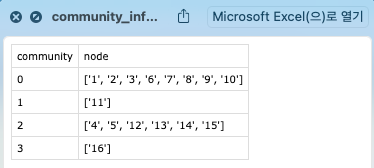

- plot은 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

####                         

#### 코드 실행

na2d.louvain(node_size_basic, node_size_multiplier, ...
    startcolor_edge, endcolor_edge , color_list_node, ...
    degree_lim, edge_lim, ...
    edge_colorbar_lim, ...
    display_community_color, display_degree, display_sync_score, display_axes, ...
    camera_up, camera_center, camera_eye);

ans = 0

# **2. 3d network 그리기**

- **데이터 파일 읽어오기 (reader = channelReader(), reader.readMultiChannelFile)**

- **networkAnalyzer 인스턴스 생성 (na = networkAnalyzer)**

- **데이터 파일을 networkAnalyzer에 전달 (na.addChannels(reader))**

- **사용하지 않는 채널 제거 (na.deleteChannel)**

- **노드 좌표 설정 (na.setChannelPosition3d)**

- **spike detection**

- **sync score 계산 및 확인**

- **network plot 그리기(3d)**

## **2.1. 데이터 파일 읽어오기**

파일을 읽어오는 방법에 대한 설명은 reading_method_guide.mlx 파일의 **2. readMultiChannelFile **섹션을 참조

reader = channelReader(); %channelReader object 생성
%                                       
tic 
%                                                        filename, channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
reader.readMultiChannelFile("/Users/jmmoon/Documents/GitHub/neurosignal-matlab/data/전체.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 64 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


toc % 코드 실행 소요시간 측정

Elapsed time is 44.180699 seconds.


## **2.2. networkAnalyzer 인스턴스 생성**

**(class) networkAnalyzer**

- 데이터를 저장하고, 그 데이터를 가지고 계산을 수행하고 그래프를 그리는 작업을 수행하는 객체입니다.

- 아래 예제에서는 na라는 이름을 가진 객체를 생성했습니다. na에게 데이터 A를 할당해 주면 앞으로 그 데이터에 대한 작업은 모두 na가 수행합니다. A에 대한 정보를 얻고 싶을 때도 항상 na를 통해서 얻습니다.

- 새로운 데이터 B를 분석할 때는 na가 아닌 다른 이름의 객체를 새로 생성한 다음 na에서 했던 것과 같은 코드를 실행하면 됩니다.

**    paramter 3개**

- `filepath`: 이 문서 파일 (summary_examples_network.mlx) 가 있는 폴더의 경로. [https://mainia.tistory.com/5112](https://mainia.tistory.com/5112) 참고.

- `pythonpath`: 코드 수행 전 필수 절차의 2번 항목에서 얻은 python 설치 경로

- `savepath`: csv 파일과 그래프 파일을 저장하는 경로

na3d = networkAnalyzer( ...
    "/Users/mac/GitHub/neurosignal-matlab", ...
    "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python", ...
    "/Users/jmmoon/Documents/GitHub/neurosignal-matlab"); %  networkAnalyzer 클래스 인스턴스 생성

ans =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/bin/python"
          Library: "/Users/jmmoon/opt/anaconda3/envs/matlab_python/lib/libpython3.9.dylib"
             Home: "/Users/jmmoon/opt/anaconda3/envs/matlab_python"
           Status: Terminated
    ExecutionMode: OutOfProcess


## **2.3. 데이터 파일을 networkAnalyzer에 전달 **

na3d.addChannels(reader); % 채널 object를 networkAnalyzer에 입력

Deleted previous data
Reading 64 channels at once...

channel number = 1
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 2
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 3
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 4
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 5
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 6
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
number of timestamps = 73727

channel number = 7
sampling rate = 24414.060481Hz
starts at 9.814671, ends at 12.834488, duration = 3.019817
num

## **2.4. 사용하지 않는 채널 제거**

이 예제에서는 1번, 8번, 64번 채널을 제거하겠습니다.

`(method) deleteChannel`

- 제거할 채널의 목록을 array로 정해주면 해당 채널을 제거합니다.

- matlab에서 array를 만드는 다양한 방법을 이용해 제거할 채널의 목록을 만들면 됩니다.

-     연속되는 숫자는 :를 사용합니다.

-     여러 array를 연결할 때는 [] 안에서 ,로 연결합니다 (아래 예시 참고)

**    paremeter 1개**

- `delete_channel_list`

delete_channel_list = [1, 8, 64];
                %채널 번호
na3d.deleteChannel(delete_channel_list);

Deleted channal 1
63 channels left
Deleted channal 8
62 channels left
Deleted channal 64
61 channels left


## 2.5. 채널 위치 입력

### **2.5.1. 방법 1 : 채널 각각의 위치를 따로 설정**

method `setChannelPosition3d`

input argument:

- channel number

- 해당 channel의 x좌표

- 해당 channel의 y좌표

- 해당 channel의 z좌표

x, y 좌표는 좌표평면의 1사분면을 생각하면 됩니다. (0,0)의 한 칸 위가 (0,1)이고 한 칸 오른쪽이 (1,0)입니다. 아래 코드로 설정한 위치를 그림으로 그리면 아래 그림처럼 됩니다.

%                 channlNum x  y  z
%na3d.setChannelPosition3d(1 , 0, 0, 0)
na3d.setChannelPosition3d(2 , 0, 1, 0)

set channel 2's position as (0.000000, 1.000000, 0.000000)


na3d.setChannelPosition3d(3 , 0, 2, 0)

set channel 3's position as (0.000000, 2.000000, 0.000000)


na3d.setChannelPosition3d(4 , 0, 3, 0)

set channel 4's position as (0.000000, 3.000000, 0.000000)


na3d.setChannelPosition3d(5 , 1, 0, 0)

set channel 5's position as (1.000000, 0.000000, 0.000000)


na3d.setChannelPosition3d(6 , 1, 1, 0)

set channel 6's position as (1.000000, 1.000000, 0.000000)


na3d.setChannelPosition3d(7 , 1, 2, 0)

set channel 7's position as (1.000000, 2.000000, 0.000000)


%na3d.setChannelPosition3d(8 , 1, 3, 0)
na3d.setChannelPosition3d(9 , 2, 0, 0)

set channel 9's position as (2.000000, 0.000000, 0.000000)


na3d.setChannelPosition3d(10, 2, 1, 0)

set channel 10's position as (2.000000, 1.000000, 0.000000)


na3d.setChannelPosition3d(11, 2, 2, 0)

set channel 11's position as (2.000000, 2.000000, 0.000000)


na3d.setChannelPosition3d(12, 2, 3, 0)

set channel 12's position as (2.000000, 3.000000, 0.000000)


na3d.setChannelPosition3d(13, 3, 0, 0)

set channel 13's position as (3.000000, 0.000000, 0.000000)


na3d.setChannelPosition3d(14, 3, 1, 0)

set channel 14's position as (3.000000, 1.000000, 0.000000)


na3d.setChannelPosition3d(15, 3, 2, 0)

set channel 15's position as (3.000000, 2.000000, 0.000000)


na3d.setChannelPosition3d(16, 3, 3, 0)

set channel 16's position as (3.000000, 3.000000, 0.000000)


na3d.setChannelPosition3d(17,  0, 0, 1.5)

set channel 17's position as (0.000000, 0.000000, 1.500000)


na3d.setChannelPosition3d(18,  0, 1, 1.5)

set channel 18's position as (0.000000, 1.000000, 1.500000)


na3d.setChannelPosition3d(19,  0, 2, 1.5)

set channel 19's position as (0.000000, 2.000000, 1.500000)


na3d.setChannelPosition3d(20,  0, 3, 1.5)

set channel 20's position as (0.000000, 3.000000, 1.500000)


na3d.setChannelPosition3d(21,  1, 0, 1.5)

set channel 21's position as (1.000000, 0.000000, 1.500000)


na3d.setChannelPosition3d(22,  1, 1, 1.5)

set channel 22's position as (1.000000, 1.000000, 1.500000)


na3d.setChannelPosition3d(23,  1, 2, 1.5)

set channel 23's position as (1.000000, 2.000000, 1.500000)


na3d.setChannelPosition3d(24,  1, 3, 1.5)

set channel 24's position as (1.000000, 3.000000, 1.500000)


na3d.setChannelPosition3d(25,  2, 0, 1.5)

set channel 25's position as (2.000000, 0.000000, 1.500000)


na3d.setChannelPosition3d(26,  2, 1, 1.5)

set channel 26's position as (2.000000, 1.000000, 1.500000)


na3d.setChannelPosition3d(27,  2, 2, 1.5)

set channel 27's position as (2.000000, 2.000000, 1.500000)


na3d.setChannelPosition3d(28,  2, 3, 1.5)

set channel 28's position as (2.000000, 3.000000, 1.500000)


na3d.setChannelPosition3d(29,  3, 0, 1.5)

set channel 29's position as (3.000000, 0.000000, 1.500000)


na3d.setChannelPosition3d(30,  3, 1, 1.5)

set channel 30's position as (3.000000, 1.000000, 1.500000)


na3d.setChannelPosition3d(31,  3, 2, 1.5)

set channel 31's position as (3.000000, 2.000000, 1.500000)


na3d.setChannelPosition3d(32,  3, 3, 1.5)

set channel 32's position as (3.000000, 3.000000, 1.500000)



na3d.setChannelPosition3d(33,  0, 0, 3)

set channel 33's position as (0.000000, 0.000000, 3.000000)


na3d.setChannelPosition3d(34,  0, 1, 3)

set channel 34's position as (0.000000, 1.000000, 3.000000)


na3d.setChannelPosition3d(35,  0, 2, 3)

set channel 35's position as (0.000000, 2.000000, 3.000000)


na3d.setChannelPosition3d(36,  0, 3, 3)

set channel 36's position as (0.000000, 3.000000, 3.000000)


na3d.setChannelPosition3d(37,  1, 0, 3)

set channel 37's position as (1.000000, 0.000000, 3.000000)


na3d.setChannelPosition3d(38,  1, 1, 3)

set channel 38's position as (1.000000, 1.000000, 3.000000)


na3d.setChannelPosition3d(39,  1, 2, 3)

set channel 39's position as (1.000000, 2.000000, 3.000000)


na3d.setChannelPosition3d(40,  1, 3, 3)

set channel 40's position as (1.000000, 3.000000, 3.000000)


na3d.setChannelPosition3d(41,  2, 0, 3)

set channel 41's position as (2.000000, 0.000000, 3.000000)


na3d.setChannelPosition3d(42,  2, 1, 3)

set channel 42's position as (2.000000, 1.000000, 3.000000)


na3d.setChannelPosition3d(43,  2, 2, 3)

set channel 43's position as (2.000000, 2.000000, 3.000000)


na3d.setChannelPosition3d(44,  2, 3, 3)

set channel 44's position as (2.000000, 3.000000, 3.000000)


na3d.setChannelPosition3d(45,  3, 0, 3)

set channel 45's position as (3.000000, 0.000000, 3.000000)


na3d.setChannelPosition3d(46,  3, 1, 3)

set channel 46's position as (3.000000, 1.000000, 3.000000)


na3d.setChannelPosition3d(47,  3, 2, 3)

set channel 47's position as (3.000000, 2.000000, 3.000000)


na3d.setChannelPosition3d(48,  3, 3, 3)

set channel 48's position as (3.000000, 3.000000, 3.000000)


na3d.setChannelPosition3d(49, 0, 0, 4.5)

set channel 49's position as (0.000000, 0.000000, 4.500000)


na3d.setChannelPosition3d(50, 0, 1, 4.5)

set channel 50's position as (0.000000, 1.000000, 4.500000)


na3d.setChannelPosition3d(51, 0, 2, 4.5)

set channel 51's position as (0.000000, 2.000000, 4.500000)


na3d.setChannelPosition3d(52, 0, 3, 4.5)

set channel 52's position as (0.000000, 3.000000, 4.500000)


na3d.setChannelPosition3d(53, 1, 0, 4.5)

set channel 53's position as (1.000000, 0.000000, 4.500000)


na3d.setChannelPosition3d(54, 1, 1, 4.5)

set channel 54's position as (1.000000, 1.000000, 4.500000)


na3d.setChannelPosition3d(55, 1, 2, 4.5)

set channel 55's position as (1.000000, 2.000000, 4.500000)


na3d.setChannelPosition3d(56, 1, 3, 4.5)

set channel 56's position as (1.000000, 3.000000, 4.500000)


na3d.setChannelPosition3d(57, 2, 0, 4.5)

set channel 57's position as (2.000000, 0.000000, 4.500000)


na3d.setChannelPosition3d(58, 2, 1, 4.5)

set channel 58's position as (2.000000, 1.000000, 4.500000)


na3d.setChannelPosition3d(59, 2, 2, 4.5)

set channel 59's position as (2.000000, 2.000000, 4.500000)


na3d.setChannelPosition3d(60, 2, 3, 4.5)

set channel 60's position as (2.000000, 3.000000, 4.500000)


na3d.setChannelPosition3d(61, 3, 0, 4.5)

set channel 61's position as (3.000000, 0.000000, 4.500000)


na3d.setChannelPosition3d(62, 3, 1, 4.5)

set channel 62's position as (3.000000, 1.000000, 4.500000)


na3d.setChannelPosition3d(63, 3, 2, 4.5)

set channel 63's position as (3.000000, 2.000000, 4.500000)


%na3d.setChannelPosition3d(64, 3, 3, 4.5)

### **2.5.2. 방법 2 : 모든 채널의 위치를 한꺼번에 설정**

채널 개수 x 3 크기의 array에 위치를 한꺼번에 입력합니다. 채널 번호가 빠른 채널의 위치부터 입력합니다. 예를 들어 채널 번호가 [1,3,4,5,10]이라면, 이 순서로 빈칸 없이 입력합니다 (예를 들어, 2번 채널의 위치는 입력하지 않습니다)

positions_input_array = [
[
0, 1, 0;
0, 2, 0;
0, 3, 0;
1, 0, 0;
1, 1, 0;
1, 2, 0;
0, 0, 0;
2, 0, 0;
2, 1, 0;
2, 2, 0;
2, 3, 0;
3, 0, 0;
3, 1, 0;
3, 2, 0;
3, 3, 0;
0, 0, 1.5;
0, 1, 1.5;
0, 2, 1.5;
0, 3, 1.5;
1, 0, 1.5;
1, 1,  1.5;
1, 2,  1.5;
1, 3,  1.5;
2, 0,  1.5;
2, 1,  1.5;
2, 2,   1.5;
2, 3,   1.5;
3, 0,   1.5;
3, 1,   1.5;
3, 2,   1.5;
3, 3,   1.5;
0,  0, 3;
0, 1, 3;
0, 2, 3;
0, 3, 3;
1, 0, 3;
1, 1, 3;
1, 2 ,3;
1, 3, 3;
2, 0, 3;
2, 1, 3;
2, 2, 3;
2, 3, 3;
3, 0, 3;
3, 1, 3;
3, 2, 3;
3, 3, 3;
0, 0, 4.5;
0, 1, 4.5;
0, 2, 4.5;
0, 3, 4.5;
1, 0, 4.5;
1,1,   4.5;
1,2,   4.5;
 1,3   4.5;
 2, 0   4.5;
 2, 1   4.5;
 2, 2   4.5;
 2, 3   4.5;
 3, 0   4.5;
 3, 1   4.5;
 3, 2   4.5;
]
   
    ];
na3d.setChannelPosition3dArray(positions_input_array)

set channel 2's position as (0.000000, 1.000000, 0.000000)
set channel 3's position as (0.000000, 2.000000, 0.000000)
set channel 4's position as (0.000000, 3.000000, 0.000000)
set channel 5's position as (1.000000, 0.000000, 0.000000)
set channel 6's position as (1.000000, 1.000000, 0.000000)
set channel 7's position as (1.000000, 2.000000, 0.000000)
set channel 9's position as (0.000000, 0.000000, 0.000000)
set channel 10's position as (2.000000, 0.000000, 0.000000)
set channel 11's position as (2.000000, 1.000000, 0.000000)
set channel 12's position as (2.000000, 2.000000, 0.000000)
set channel 13's position as (2.000000, 3.000000, 0.000000)
set channel 14's position as (3.000000, 0.000000, 0.000000)
set channel 15's position as (3.000000, 1.000000, 0.000000)
set channel 16's position as (3.000000, 2.000000, 0.000000)
set channel 17's position as (3.000000, 3.000000, 0.000000)
set channel 18's position as (0.000000, 0.000000, 1.500000)
set channel 19's position as (0.000000, 1.00000

## 2.6. 모든 채널에 bandpass 적용하고 spike detection 수행

summary_examples_firing_rate.mlx 파일의 [0.4. bandpass filter 적용] [0.5. (method) `detectSpikes] 섹션 참조`

tic
na3d.bandPass([300,3000])
na3d.detectSpikes(4.5,2,2);

channel 2 number of spikes found : 85
channel 3 number of spikes found : 110
channel 4 number of spikes found : 231
channel 5 number of spikes found : 287
channel 6 number of spikes found : 57
channel 7 number of spikes found : 58
channel 9 number of spikes found : 120
channel 10 number of spikes found : 74
channel 11 number of spikes found : 14
channel 12 number of spikes found : 243
channel 13 number of spikes found : 274
channel 14 number of spikes found : 256
channel 15 number of spikes found : 292
channel 16 number of spikes found : 5
channel 17 number of spikes found : 138
channel 18 number of spikes found : 60
channel 19 number of spikes found : 244
channel 20 number of spikes found : 279
channel 21 number of spikes found : 272
channel 22 number of spikes found : 34
channel 23 number of spikes found : 54
channel 24 number of spikes found : 28
channel 25 number of spikes found : 53
channel 26 number of spikes found : 64
channel 27 number of spikes found : 100
channel 28 number of

toc

Elapsed time is 34.630242 seconds.


### **2.6.1 channel별 spike 평균 amplitude**

(2023년 7월 18일 추가)

`(method) getMeanSpikeAmplitude`

- 제거할 채널의 목록을 array로 정해주면 해당 채널을 제거합니다.

- matlab에서 array를 만드는 다양한 방법을 이용해 제거할 채널의 목록을 만들면 됩니다.

-     연속되는 숫자는 :를 사용합니다.

-     여러 array를 연결할 때는 [] 안에서 ,로 연결합니다 (아래 예시 참고)

- 오류가 나면, 입력한 범위 안에 spike가 없어서 생긴 오류일 가능성이 높습니다. 여러 범위 값을 시도해 보세요.

**    paremeter 3개**

- `range_start: `계산에 포함할 spike 시간 범위의 시작점 (초 단위)

- `range_end: `계산에 포함할 spike 시간 범위의 끝점 (초 단위)

- `isRaw``: true`이면 raw signal에서의 amplitude로 계산합니다. `false`이면 filtered signal에서의 amplitude로 계산합니다.

format long

na3d.getMeanSpikeAmplitude(5,10, true)

ans = 61×1 table
                  average_amp     
              ____________________

    node2      0.00115147475150811
    node3     0.000148556628827814
    node4     0.000132476273019592
    node5     0.000115885843781088
    node6      0.00024807688448271
    node7     0.000258863187989011
    node9      0.00119804581197871
    node10    0.000793144163261827
    node11    1.16177107364819e-05
    node12    0.000132733116006486
    node13    0.000136431548450352
    node14    0.000117912717739454
    node15    0.000126979023008646
    node16     6.1029429309826e-06
    node17    2.08735055618229e-06
    node18    2.12429118206996e-05


### **2.6.2. 통합 raster plot **

`(class) drawer_raster_instance`

- raster plot을 만드는 작업을 하는 객체를 생성하는 class입니다. 향후 summary_examples_multichannel, summary_examples_�firing_rate 등 여러 파일에 서로 다르게 작성되어 있는 raster plot 그리는 코드를 이 class를 이용해 통합하고자 합니다.

`(method) drawRaster`

- 채널 하나의 raster plot을 그립니다. 

**    paremeter 1개**

- `channel: `raster plot을 그릴 `channel` object. spike detection을 이미 한 상태여야 함

- `color: `계산에 포함할 spike 시간 범위의 시작점 (초 단위)

`(method) drawRasterAll`

- 채널 여러 개의 raster plot을 한번에 그립니다. networkAnalyzer 

**    paremeter 2개**

- `multichannal_instance: `raster plot을 그릴 `channel` object들을 보유하고 있는 object. 우선 networkAnalyzer를 지원하도록 코드를 작성하였습니다. 향후 summary_examples_multichannel나 summary_examples_�firing_rate에 있는 obejct들도 지원하게 수정하겠습니다.

- `color: `계산에 포함할 spike 시간 범위의 시작점 (초 단위)

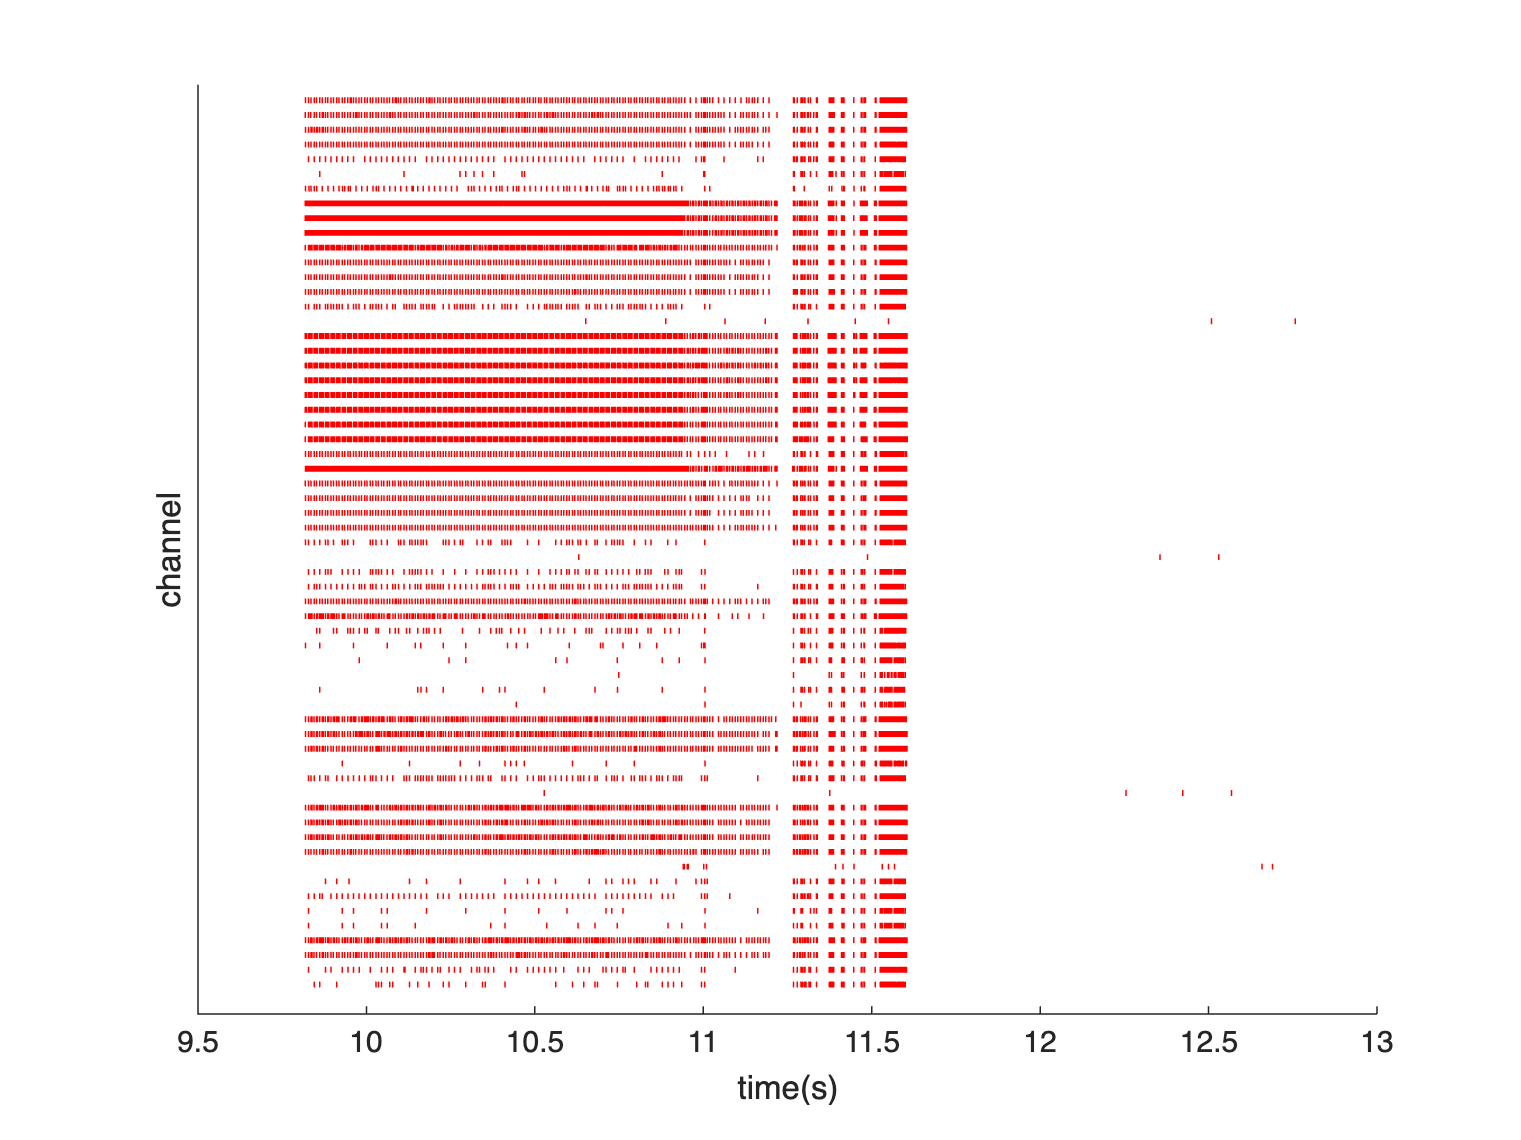

ans =     63
    62
    61
    60
    59
    58
    57
    56
    55
    54


drawer_raster_instance = drawer_raster();
%multiple raster plot
figure
drawer_raster_instance.drawRasterAll(na3d, 'red')

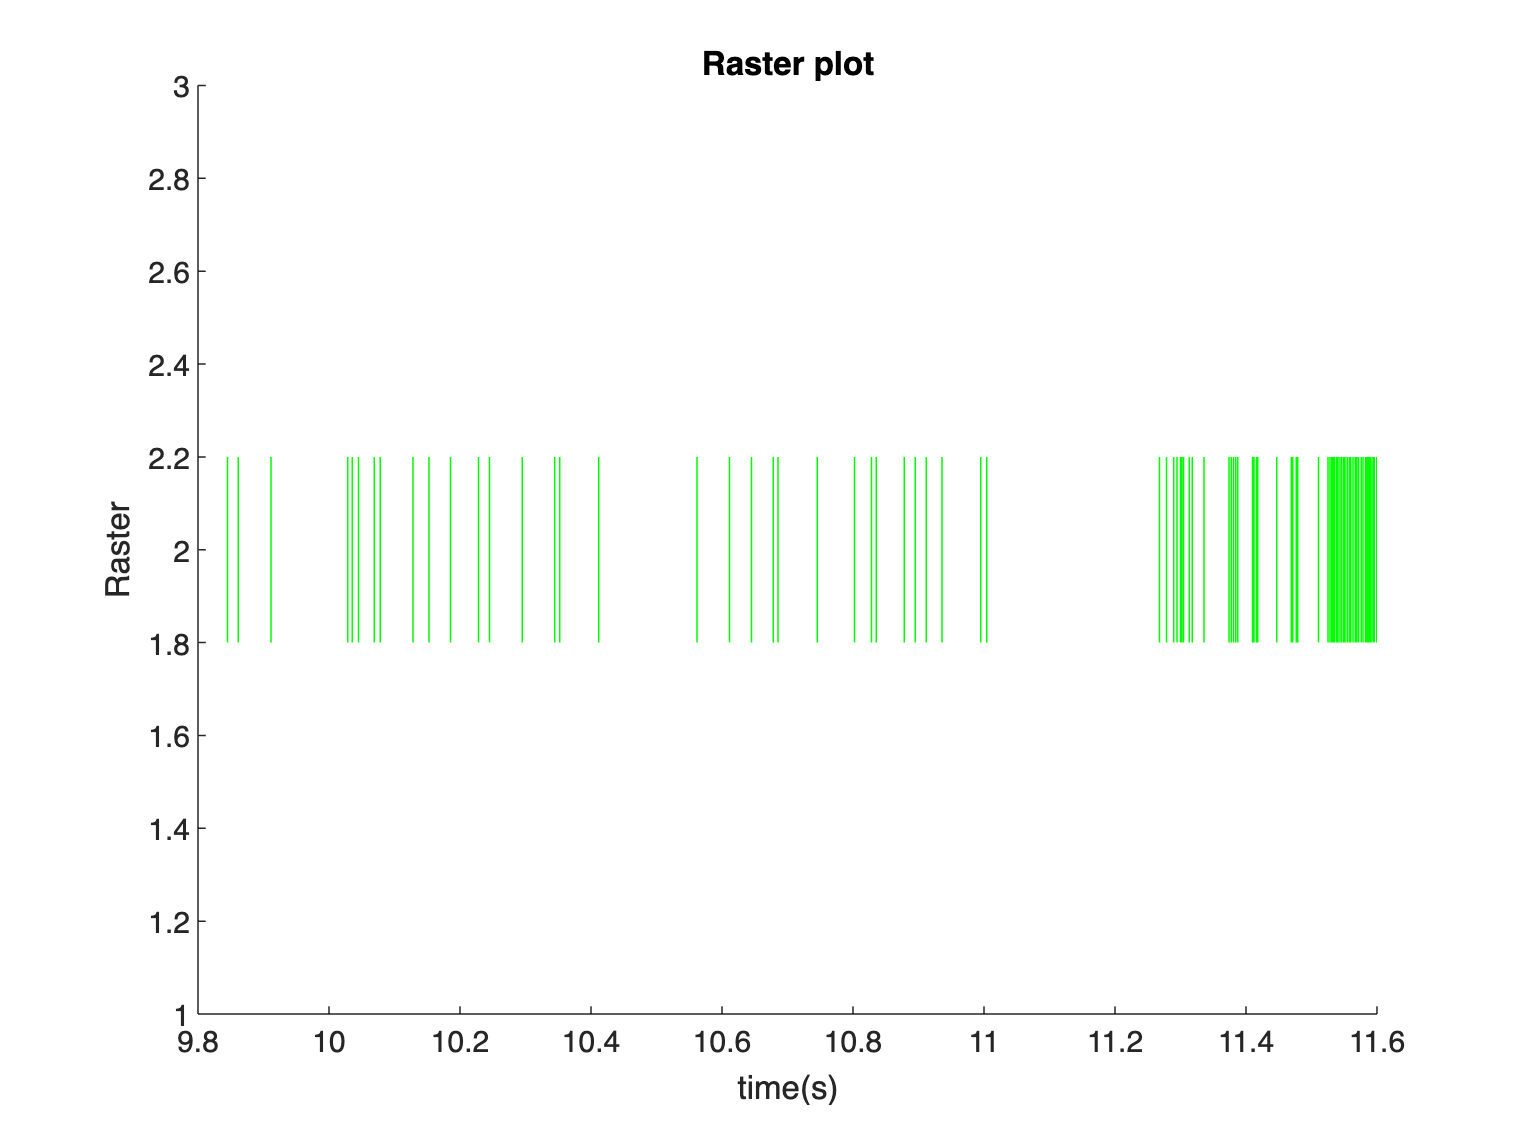


figure
% signle raster plot
                                        % channel 번호
drawer_raster_instance.drawRaster(na3d.channels(2), 'green')

## **2.7. sync score 계산 및 확인**

**(method) spikeDist**

- pyspike 패키지의 spike_sync 함수를 이용해 spike train 간의 유사도 (= 1 - 거리)를 측정합니다.

- spike train간의 유사도이기 때문에 각 채널에 spike가 0개이면 sync score 계산값이 NaN이 됩니다.

- NaN 값이 나오지 않게 하려면 section 5의 코드에서 첫 번째 파라미터(표준편차에 곱해지는 수)를 작게 하여 더 많은 spike가 발견되도록 하면 됩니다.

**    paramter 3개**

- `thres`: thres 값을 0.5로 설정하면, sync score 0.5 이상일 경우에만 두 채널이 연결된 것으로 간주합니다.

- `is_normalize`: true로 하면 random spike trains 두 개를 생성해 그 사이의 sync score를 계산하는 작업을 n_simul번 반복하고 그 결과 얻은 n_simul개 sync score의 평균값을 원래 sync score에서 뺍니다 (0보다 작은 값이 나올 경우 0으로 만듭니다). **계산 횟수가 n_simul배 늘어나므로 계산에 시간이 매우 많이 걸립니다 (채널 10개로 약 20분이 걸립니다).** false로 하면 위 작업을 수행하지 않고 원래 sync score 값을 사용합니다.

- `n_simul`: random spike trains 생성 갯수. Reference 논문에서는 1000회입니다.

tic %실행시간 측정 시작
thres = 0.3; %sync score 0.3 이상일 경우에만 연결된 것으로 간주 (network를 그릴 때에만 적용됨)
           % thres  is_normalize, n_simul
na3d.spikeDist(thres, false, 100);

calculating sync score between 1th and other channels...
calculating sync score between 2th and other channels...


### network mapping 을 위해 계산하는 parameter 확인

아래 행렬의 i,j번째 성분이 i번째 노드와 j번째 노드 간의 syncronized score를 의미합니다

na3d.syncScores

아래는 각 노드에 연결된(sync score > thres) 노드의 개수를 나타냅니다.

na3d.nConnects
max(na3d.syncScores{:,:}) %각 channel별 sync score 최댓값

max(max(na3d.syncScores{:,:})) %전체 sync score 중 최댓값

na3d.nConnects
max(na3d.nConnects{:,:}) %각 channel별 degree 최댓값

max(max(na3d.nConnects{:,:})) %전체 degree 중 최댓값

## **2.8. network 그룹 개수 파악하기**

network plot을 그리기 전에 각 그룹에 서로 다른 색깔을 할당하기 위해 그룹 개수를 먼저 파악합니다. 실행에 10초 정도 소요됩니다.

tic % 실행시간 측정 시작
n_group = na3d.get_group_info();
toc % 실행시간 측정 끝
random_node_color = rgb2hex(rand([n_group 3]));

## 2.9. network plot 그리기(3d)

이 섹션은 바로 실행되지 않습니다. 색깔 관련 변수들을 직접 설정해 주셔야 실행됩니다.

`(method) louvain`

- 네트워크 모양을 plot으로 그릴 때 필요한 python의 matplotlib 라이브러리가 matlab 상에서 py.xxx 명령어로 실행되지 않아서, pyrun("xxx")를 이용해 네트워크를 만들고 그림을 그리는 코드가 들어 있는 `drawnx.py `파일을 통째로 실행합니다.

- sync score>=thres 이상인 경우만 edge로 연결되며, sync score가 높을수록 edge가 빨간색이 됩니다. 노드 색깔은 그룹을 의미합니다.

- 같은 커뮤니티에 속하는 노드(전극)들은 같은 색깔로 표시됩니다.

- edge의 색깔은 sync score값을 나타냅니다.

**   paremeter 15개**

- `node_size_basic`

- `node_size_multiplier`

- `startcolor_edge`

- `endcolor_edge`

- `color_list_node`

- `degree_lim`

- `edge_lim`

- `edge_colorbar_lim`

- `display_community_color`

- `display_degree`

- `display_sync_score`

- `display_axes`

- `camera_up`

- `camera_center`

- `camera_eye`

#### [1-2] Node size parameters

노드에 연결된 다른 노드 수(degree)가 클수록 노드 사이즈가 커집니다. 

node size = node_size_basic + node_size_multiplier * relative_degree

따라서 degree가 가장 작은 노드의 크기는 node_size_basic, degree가 가장 큰 노드의 크기는 node_size_basic+node_size_multiplier가 됩니다.

- `node_size_basic`: degree가 가장 작은 node의 크기

- `node_size_multiplier`: degree가 1씩 커질 때마다 node size가 얼마나 커질지를 결정합니다. degree는 max degree = 1, min degree = 0으로 normalize한 값을 사용합니다.

%1
node_size_basic = 10;

%2
node_size_multiplier = 20;

#### [3-5] Color paramters

edge와 node의 색깔을 결정합니다. Edge의 값은 연속형이기 때문에 color scale로 색깔을 표시하는 반면, node의 group 번호는 이산형이기 때문에 color list로 색깔을 표시합니다. Edge 색깔을 위한 color scale은 시작 색깔 (`startcolor_edge`)과 종료 색깔 (`endcolor_edge`)을 정하여 생성합니다. Node 색깔을 위한  color list는 직접 입력하거나, 1.8에서 생성된 `random_node_color`를 사용할 수 있습니다. 색깔은 모두 hex 코드로 입력하며, hex 코드는 https://www.color-hex.com/ 에서 검색해서 찾으시면 됩니다.

- `startcolor_edge`: edge 색깔을 위한 color scale의 시작 색깔 hex code

- `endcolor_edge`: edge 색깔을 위한 color scale의 종료 색깔 hex code

- `color_list_node`: node 그룹 개수에 맞게 색깔 hex 코드의 array를 만들어 입력합니다. 이 예제에서는 그룹이 2개이므로 원소가 2개인 array를 만듭니다. 

%3
startcolor_edge = '#9fcbee'; % #9fcbee indicates skyblue

%4
endcolor_edge =  '#01016f'; % #01016f indicates indico

%5
% color_list_node = ['#802000', '#ecdec2']; % 직접 지정할 때
% #802000 indicates brown, #ecdec2 indicates yellow

color_list_node = random_node_color;

#### [6-7] Display range paramters

네트워크를 그림으로 그릴 때 특정 범위 밖의 node나 edge를 숨기는 기능입니다. 앞에서 `spikeDist를` 실행할 때 사용한 `thres`와는 달리, 계산과정에는 영향을 미치지 않습니다. 계산과정에서 edge의 유무에 따라 group 형성 결과가 달라지기 때문에, `thres` 값 조절과 여기의 파라미터 값 조절은 서로 다른 역할을 합니다.

- `degree_lim`: Degree가 이 범위 내에 있는 node만 plot에 표시됩니다. 앞에서 channel을 지우는 것과 달리, 계산과정 자체에는 포함됩니다. na.nConnects로 degree 범위를 확인한 다음 적절한 값을 설정하세요.

- `edge_lim`: % Sync score가 이 범위 내에 있는 edge만 plot에 표시됩니다. na.syncScores로 sync score 범위를 확인한 다음 적절한 값을 설정하세요.

%6
degree_lim = [0, 100]; 

%7
edge_lim = [thres, 1]; 

#### [8] Colarbar range paramter

여러 plot의 sync score colorbar 범위를 통일시키기 위한 기능입니다.각 plot마다 edge value 값의 범위가 다 다르기 때문에, 여러 plot의 edge들에서 같은 edge 값이면 같은 색으로 칠해지도록 하기 위함입니다.

- `edge_colorbar_lim`: colorbar의 범위를 정합니다. 이 값은 edge_lim 값과 달라도 되지만 edge_lim을 포함하는 범위여야 합니다.

%8
edge_colorbar_lim = [thres, 1]; 

#### [9-12] Display on/off options

그림에서 특정 요소를 표시할지 여부를 결정합니다. true로 지정하면 해당 요소를 표시합니다.

- `display_community_color`: true이면 각 node를 소속 group의 색으로 칠합니다.

- `display_degree`: true이면 degree에 따라 node 크기를 다르게 그립니다.

- `display_sync_score`: true이면 sync score에 따라 edge 색깔을 다르게 합니다.

- `display_axes`: true이면 좌표축을 표시합니다.

%9
display_community_color= true;

%10
display_degree = true;

%11
display_sync_score = true;

%12
display_axes = false;

#### [13-15] Camera options

[https://wearablelab-camera-5ti4.onrender.com](https://wearablelab-camera-5ti4.onrender.com) 에서 적절한 각도를 설정한 뒤 (접속에 1분 정도 걸립니다), plot 위에 나타나는 좌표값에서 (scene.camera... 부분)

up, center, eye의  x,y,z좌표를 가져와 아래에 순서대로 입력합니다. 또는 [https://plotly.com/python/3d-camera-controls/](https://plotly.com/python/3d-camera-controls/) 의 설명을 참고하여 값을 정합니다.

- `up`: orbital rotation 기능을 사용하면 바뀌는 값입니다. 2d network에서는 사용할 일이 없습니다.

            

- `center`: pan 기능을 사용해 plot 자체를 상하좌우로 움직이면 바뀌는 값입니다. Colorbar와 plot이 겹치지 않도록 할 때 사용합니다.

                        

- `eye`: turntable rotation 기능을 사용해 plot을 돌리면 바뀌는 값입니다. html 파일을 열면 기본적으로 이 기능이 켜져 있습니다. 

                

%13
camera_up = [0,0,1];

%14
camera_center = [ -0.026808540619146986, 0.17893492675254555, -0.0037298777892444917];

%15
camera_eye = [-0.02680854061914685,  0.17893492675254555, 2.18482863252269]; %2d 네트워크를 위에서 볼 때는 eye 값은 이 값을 사용합니다.

위에서 parameter 값을 모두 설정했으므로, 아래 함수는 고칠 필요가 없습니다. 아래 함수를 실행한 다음에, 각 커뮤니티에 속하는 노드 번호를 community_info.csv 파일을 통해 확인하실 수 있습니다.

                            

- plot은 이 파일이 있는 폴더에 networkfig.html, networkfig.svg로 저장됩니다.

####                         

#### 코드 실행

na3d.louvain(node_size_basic, node_size_multiplier, ...
    startcolor_edge, endcolor_edge , color_list_node, ...
    degree_lim, edge_lim, ...
    edge_colorbar_lim, ...
    display_community_color, display_degree, display_sync_score, display_axes, ...
    camera_up, camera_center, camera_eye);